# A-star Algorithm on a grid

The skeleton code below contains some of the code needed to implement the A Star algorithm on a grid based environment. 

Your job is to complete the function by finishing the marked section of the file. The code is designed to maintain the following 2D arrays:

    • `g`**:** This array encodes the current estimate for the distance between each node and the start node 

    • `f`**:**  This array encodes the sum of the `g` value for each node and the value of the `Heuristic function`, `H`. The code that we have provided already computes an array, `H`, with appropriate heuristic function values for each node.

The `map` and the `parent` arrays carry out the same function as in `DijkstraGrid` 

On every iteration through the main loop the code finds the unvisited cell with the smallest `f` value. 

The part of this function that you need to write should consider the four neighbors of the cell to the north, south east and west and for each neighbor it should decide if it needs to update the corresponding entries in the f, g, map and parent arrays.

If you know how to use sub functions in Matlab you may find it useful to create one that you can then apply repeatedly to each of the neighboring cells, but this is not required.

Once completed, run the script and pass the subsequent testcases.

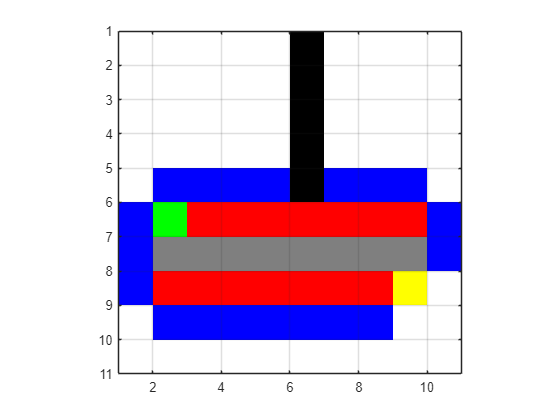

map = false(10); % Input map parameters
map (1:5, 6) = true; % Obstacle Declaration
start_coords = [6, 2]; % Starting coordinates
dest_coords  = [8, 9]; % Destination Coordinates
drawMapEveryTime = true; % Display Outputs
[route, numExpanded] = AStarGrid(map, start_coords, dest_coords, drawMapEveryTime); % Implementation

function [route,numExpanded] = AStarGrid (input_map, start_coords, dest_coords, drawMapEveryTime)
    % Run A* algorithm on a grid.
    % Inputs : 
    %   input_map : a logical array where the freespace cells are false or 0 and
    %   the obstacles are true or 1
    %   start_coords and dest_coords : Coordinates of the start and end cell
    %   respectively, the first entry is the row and the second the column.
    % Output :
    %    route : An array containing the linear indices of the cells along the
    %    shortest route from start to dest or an empty array if there is no
    %    route. This is a single dimensional vector
    %    numExpanded: Remember to also return the total number of nodes
    %    expanded during your search. Do not count the goal node as an expanded node. 
    
    % set up color map for display
    % 1 - white - clear cell
    % 2 - black - obstacle
    % 3 - red = visited
    % 4 - blue  - on list
    % 5 - green - start
    % 6 - yellow - destination
    
    cmap = [1 1 1; ...
            0 0 0; ...
            1 0 0; ...
            0 0 1; ...
            0 1 0; ...
            1 1 0; ...
            0.5 0.5 0.5];
    
    colormap(cmap);
    
    [nrows, ncols] = size(input_map);
    
    % map - a table that keeps track of the state of each grid cell
    map = zeros(nrows,ncols);
    
    map(~input_map) = 1;   % Mark free cells
    map(input_map)  = 2;   % Mark obstacle cells
    
    % Generate linear indices of start and dest nodes
    start_node = sub2ind(size(map), start_coords(1), start_coords(2));
    dest_node  = sub2ind(size(map), dest_coords(1),  dest_coords(2));
    
    map(start_node) = 5;
    map(dest_node)  = 6;
    
    % meshgrid will `replicate grid vectors' nrows and ncols to produce
    % a full grid
    % type `help meshgrid' in the Matlab command prompt for more information
    parent = zeros(nrows,ncols);
    
    [X, Y] = meshgrid (1:ncols, 1:nrows);
    
    xd = dest_coords(1);
    yd = dest_coords(2);
    
    % Evaluate Heuristic function, H, for each grid cell
    % Manhattan distance
    H = abs(X - xd) + abs(Y - yd);
    H = H';
    % Initialize cost arrays
    f = Inf(nrows,ncols);
    g = Inf(nrows,ncols);
    
    g(start_node) = 0;
    f(start_node) = H(start_node);
    
    % keep track of the number of nodes that are expanded
    numExpanded = 0;
    
    % Main Loop
    while true
        % Draw current map
        map(start_node) = 5;
        map(dest_node) = 6;
        
        % make drawMapEveryTime = true if you want to see how the 
        % nodes are expanded on the grid. 
        if (drawMapEveryTime)
            image(1.5, 1.5, map);
            grid on;
            axis image;
            drawnow;
        end
        
        % Find the node with the minimum f value
        [min_f, current] = min(f(:));
        
        if ((current == dest_node) || isinf(min_f))
            break;
        end
        
        % Update input_map
        map(current) = 3;
        f(current) = Inf; % remove this node from further consideration
        
        % Compute row, column coordinates of current node
        [i, j] = ind2sub(size(f), current);
        
        % *********************************************************************
        % ALL YOUR CODE BETWEEN THESE LINES OF STARS
        % Visit all of the neighbors around the current node and update the
        % entries in the map, f, g and parent arrays
        %
        
        numExpanded=numExpanded+1;
        
        for n = (j-1):2:(j+1)
            if (n>=1) && (n<=ncols)
               neighboors = sub2ind(size(map), i, n);

               if (map(neighboors) == 1)|| (map(neighboors) == 6)
                   map(neighboors) = 4;
                   g(neighboors)= g(current) + 1;
                   f(neighboors)= g(neighboors) + H(neighboors);
                   parent(neighboors) = current;
               end
            end
        end
        
        for k = (i-1):2:(i+1)
            if (k>=1) && (k<=nrows)
                neighboors = sub2ind(size(map), k, j);
                 %disp([k j]); pause
               if (map(neighboors) == 1) || (map(neighboors) == 6)
                   map(neighboors) = 4;
                   g(neighboors)= g(current) + 1;
                   f(neighboors)= g(neighboors) + H(neighboors);
                   parent(neighboors) = current;
               end
            end
        end
    end
        
        %*********************************************************************
    
    %% Construct route from start to dest by following the parent links
    if (isinf(f(dest_node)))
        route = [];
    else
        route = [dest_node];
        
        while (parent(route(1)) ~= 0)
            route = [parent(route(1)), route];
        end
    
        % Snippet of code used to visualize the map and the path
        for k = 2:length(route) - 1        
            map(route(k)) = 7;
            pause(0.1);
            image(1.5, 1.5, map);
            grid on;
            axis image;
        end
    end
end